## **Driver test program to check Clothoids library**

**Bounding box with triangles**

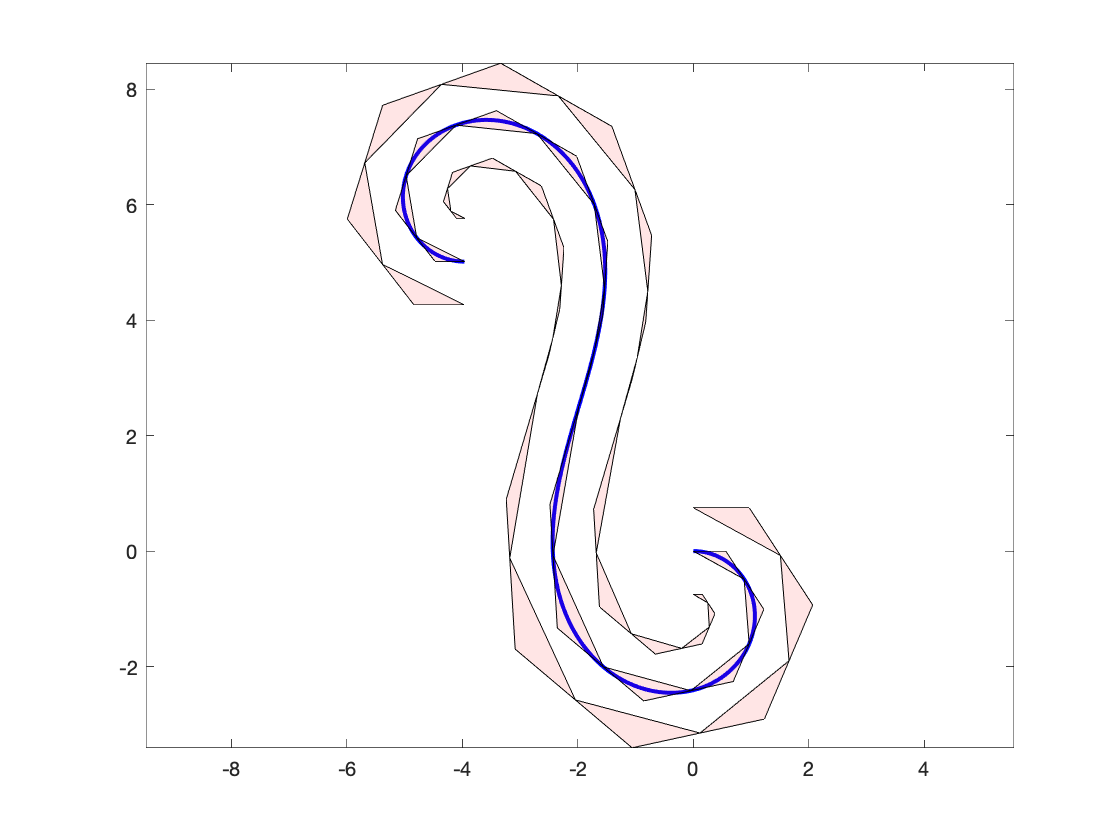

close all;

x0        = 0;
y0        = 0;
theta0    = 0;
kappa     = -1;
dkappa    = 0.1;
L         = 20;

CLOT = ClothoidCurve( x0, y0, theta0, kappa, dkappa, L );

npts = 1000;
CLOT.plot(npts,'Color','blue','LineWidth',2);
hold on;

max_angle = pi/3;
max_size  = 100;

for offs=[-0.75,0,0.75]
  [P1,P2,P3] = CLOT.bbTriangles( max_angle, max_size, offs );
  
  for i=1:size(P1,2)
    fill( [P1(1,i),P2(1,i),P3(1,i)], ...
          [P1(2,i),P2(2,i),P3(2,i)], ...
          'red','FaceAlpha',0.1);
  end
end
%plot( XY(1,:), XY(2,:), '-b', 'LineWidth', 2 );

axis equal;